%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.02; % secs
t = 0 : t_step : t_end;

main = load('data/got_tau_1.mat');
extra = load('data/got_tau_extra.mat');

Qs = [extra.Qs main.Qs];
Ts = main.Ts;
L_Qs = length(Qs);
L_Ts = length(Ts);

best_rmss = cat(2, extra.best_rmss, main.best_rmss);
dynamic_powers = cat(2, extra.dynamic_powers, main.dynamic_powers);
static_powers = cat(2, extra.static_powers, main.static_powers);


num = L_Qs * L_Ts;
Q_for_plot = zeros(1, num);
T_for_plot = zeros(1, num);
rms_for_plot = zeros(1, num);
ratio_for_plot = zeros(1, num);

best_rms_mean = zeros(L_Qs, L_Ts);
dynamic_mean  = zeros(L_Qs, L_Ts);
static_mean   = zeros(L_Qs, L_Ts);

% remove 5 smallest and 5 biggest values over the repeats
for j = 1 : L_Qs
    for k = 1 : L_Ts
        rms_reps = sort(best_rmss(:, j, k));
        static_reps = sort(static_powers(:, j, k));
        dynamic_reps = sort(dynamic_powers(:, j, k));
        
        % now remove the smallests and biggests
        rms_reps(1:5) = [];
        rms_reps(end-4:end) = [];
        static_reps(1:5) = [];
        static_reps(end-4:end) = [];
        dynamic_reps(1:5) = [];
        dynamic_reps(end-4:end) = [];
        
        best_rms_mean(j, k) = mean(rms_reps);
        dynamic_mean(j, k)  = mean(dynamic_reps);
        static_mean(j, k)   = mean(static_reps);
    end
end

%best_rms_mean = mean(best_rmss, 1);
%dynamic_mean = mean(dynamic_powers, 1);
%static_mean  = mean(static_powers,  1);

count = 0;
 
for j = 1 : L_Qs
    Q = Qs(j);
    
    for k = 1 : L_Ts
        count = count + 1;
        
        T = Ts(k);
        r = best_rms_mean(j, k);
%         if r > 500
%             r = 600
%         end
        
        Q_for_plot(count) = Q;
        T_for_plot(count) = T;
        rms_for_plot(count) = r;
        %[sm, in] = max(dynamic_mean(:, k));
        %[sm, in] = max(dynamic_mean(:, k));
        sm = dynamic_mean(6, k);
        %Qs(in)
%         sm = static_mean(1, j, k);
%         if j ~= 1
%            if dynamic_mean(1, j-1, k) > sm
%                 [sm, in] = max(dynamic_mean(1, :, k));
%                 Qs(j)
%                 %sm = dynamic_mean(1, 5, k);
%            end
%         end
        ratio_for_plot(count) = dynamic_mean(j, k) / sm;
    end
end

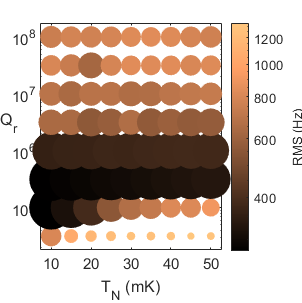

adstyle(8, 8)
%scatter(T_for_plot, Q_for_plot, 500, log(log(rms_for_plot)), 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, -300 + 100000./log10(rms_for_plot).^5, rms_for_plot, 'filled')
scatter(T_for_plot*1e3, Q_for_plot, (-400 + 40000./log10(rms_for_plot).^4)*1.5, rms_for_plot, 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, 140-log10(rms_for_plot), rms_for_plot, 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, 15000000./log10(rms_for_plot).^12, rms_for_plot, 'filled')
%scatter(T_for_plot*1e3, Q_for_plot, 1000, rms_for_plot, 'filled')
%scatter(T_for_plot, Q_for_plot, 200000./rms_for_plot, rms_for_plot, 'filled')
set(gca, 'yscale','log')
set(gca, 'colorscale','log')
axis('padded')
c = colorbar();%'Ticks', [5e2 1e3 2e3 4e3]);
ylabel(c, 'RMS (Hz)')

yticks([1e5 1e6 1e7 1e8])

%map = [1*linspace(0, 1, 500).^.3' 0.38*linspace(0, 1, 500).^.3' (1 - linspace(0, 0.2, 500).^.3)']
%map(end,:)

% colorbar - need to find where there is no match - ie if you draw a line
% right through the middle, and that should be the end of the color scale
% p = bone in command window
%pink_alt = p(1:end*0.8,:);
%map = [pink_alt; repmat(pink_alt(end,:), 500, 1)];
%colormap(map)
colormap(copper)
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')
set(get(gca,'ylabel'), 'rotation',0)%, 'VerticalAlignment','middle')
saveas(gca, 'figures/quality_of_lock.eps', 'epsc');

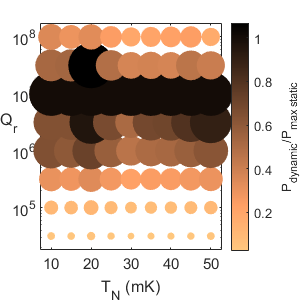

adstyle(8, 8)
scatter(T_for_plot*1e3, Q_for_plot, 1100*ratio_for_plot, ratio_for_plot, 'filled')
set(gca, 'yscale','log')
axis('padded')
c = colorbar();
ylabel(c, 'P_{dynamic}/P_{max static}')
colormap(flipud(copper))
box('on')
xlabel('T_N (mK)')
ylabel('Q_r')
set(get(gca,'ylabel'), 'rotation',0)%, 'VerticalAlignment','middle')

yticks([1e5 1e6 1e7 1e8])
saveas(gca, 'figures/main_results.eps', 'epsc');